clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';



side_faces_transformed1 = side_faces_transformed1(1:50,:);
side_faces_transformed2 = side_faces_transformed2(1:50,:);
side_faces_transformed3 = side_faces_transformed3(1:50,:);
side_faces_transformed4 = side_faces_transformed4(1:50,:);
side_faces_transformed5 = side_faces_transformed5(1:50,:);
side_faces_transformed6 = side_faces_transformed6(1:50,:);
side_faces_transformed7 = side_faces_transformed7(1:50,:);
side_faces_transformed8 = side_faces_transformed8(1:50,:);



PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./4;
phi = pi./2 - phi;
shenglunum = 4;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.08;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed5',side_faces_transformed8',side_faces_transformed4',side_faces_transformed7',side_faces_transformed3',side_faces_transformed6',side_faces_transformed2',side_faces_transformed1',P_bound1,P_bound2,0.2);

% 第一、八个平面xyz
% P1、P2、PAB、phi、shenglushu、Ti,a,distanceThreshold
% side_faces_transformed5',side_faces_transformed4',side_faces_transformed3',side_faces_transformed2',side_faces_transformed1',side_faces_transformed8',side_faces_transformed7',side_faces_transformed6'
% side_faces_transformed5',side_faces_transformed8',side_faces_transformed4',side_faces_transformed7',side_faces_transformed3',side_faces_transformed6',side_faces_transformed2',side_faces_transformed1'

## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed5',side_faces_transformed8',side_faces_transformed4',side_faces_transformed7',side_faces_transformed3',side_faces_transformed6',side_faces_transformed2',side_faces_transformed1',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

PointTable_A_off8 =    -3.1496   -0.3755   -0.2279   -0.1148    0.5225    0.4838   -0.7171   -0.8302
   -2.2644    0.2612    0.0314   -0.1447    0.5071    0.7577   -0.0845    0.0916
    2.3848    0.5770    0.4442    0.3424   -0.0665   -0.0110    0.7953    0.8971


PointTable_B_off8 =    -0.1396   -0.7175   -0.5700   -0.4568    1.1825    1.5498   -0.3750   -0.4881
    0.2354    0.0962   -0.1336   -0.3097   -0.3847   -0.2289    0.0805    0.2566
    1.4051    0.4823    0.3495    0.2477    2.2097    2.8804    0.8900    0.9918


XieMianPianYi =     0.0145         0         0         0    0.0139    0.0139         0         0


## 验证

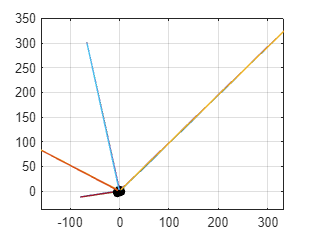

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')